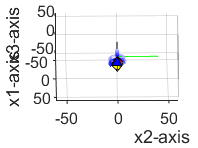

% 8
% 3번 예제에 따라 Diamond를 회전시키되 관찰자도 이 물체의 공전 궤도 외부를 회전하면서 동시에 상하로 움직인다
% 이에 따라 팔면체는 관찰자에 가까이 오기도 하고 멀어지기도 한다
%  상부 꼭지점에 부분적인 궤적을 남기도록 하면서 이를 애니메이션 하라.

% *** (예제7과 다른 점)적도의 꼭지점 하나의 궤적도 같이 그려라 ***

% Azimuth : 직선운동 하는 동안 0부터 +90deg까지 변화, 나선운동하는 동안 +90부터 +450 deg까지 변화
% Elevation : 직선운동 하는 동안 +45deg 고정, 나선운동 하는 동안 +45부터 -30deg까지 2번 반복(사인 2파장)
clear all;
close all;

d=[0 5 5 0 -5 5 0 -5 -5 0 5 -5 0;
    0 -5 5 0 5 5 0 5 -5 0 -5 -5 0;
    20 0 0 20 0 0 -20 0 0 -20 0 0 20;
    1 1 1 1 1 1 1 1 1 1 1 1 1];
p=[1 2 3;4 5 6;5 6 7;8 9 10;9 10 11;11 12 13;1 8 9;2 3 7];
c=['b';'r';'g';'w';'k';'c';'m';'y'];

orbit1=zeros(80,3);
orbit2=zeros(80,3);
% 40 X 3 0으로 채운 행렬
% 나중에 팔면체가 거쳐온 최근 40개의 좌표들만 저장할 수 있는 행렬로 사용된다.
% 따라서 부분적인 궤적을 남기도록 하는 애니메이션 구현에 필요한 변수이다.


linc1=[linspace(1,0,size(orbit1,1)); linspace(1,0,size(orbit1,1));linspace(1,1,size(orbit1,1))]';
linc2=[linspace(1,0,size(orbit2,1)); linspace(1,0,size(orbit2,1));linspace(1,1,size(orbit2,1))]';
% 1,2열은 1행부터 40행까지 1에서 0을 40등분/3열은 1행부터 40행까지 1
% 나중에 line()에서 color기능으로 가장 최신의 좌표일 수록 진하게 출력할 것인데
% color의 색깔 농도는 0~1로 설정해야 하기 때문에 (slide 3참고)

x3=0;
orbit1(end,:)=[0 0 20];
orbit2(end,:)=[5 -5 0];
% orbit1은 팔면체의 상부 꼭지점의 궤도를 저장하는 행렬로 쓸 것이다.
% orbit2은 팔면체의 5, -5, 0 좌표의 꼭지점의 궤도를 저장하는 행렬로 쓸 것이다.
el=45;


noRev=2; % 공전

for x1=[0:0.3:20] % x1축 방향으로 20만큼 surge (자전O 공전 X)
    clf;
    psi=4*pi*x1/20;
    Rz_u=[cos(psi) -sin(psi) 0 x1;
          sin(psi)  cos(psi) 0 0;
          0         0        1 0;
          0         0        0 1]; % x1/20 * 2만큼 yaw(자전) , x1만큼 surge
    y=Rz_u*d; % 팔면체 도형을 yaw and surge한 행렬을 -> y에 저장

    line([y(1,:) y(1,1)],[y(2,:) y(2,1)],[y(3,:) y(3,1)]);
    line([40 0 0],[0 0 0],[0 0 0],'Color','r'); 
    line([0 0 0],[0 40 0],[0 0 0],'Color','g'); 
    line([0 0 0],[0 0 0],[0 0 40],'Color','k');

    orbit1=circshift(orbit1,-1);
    orbit2=circshift(orbit2,-1);
    orbit1(end,:)=[y(1,1) y(2,1) y(3,1)];
    orbit2(end,:)=[y(1,2) y(2,2) y(3,2)];
    % 누적된 좌표가 과거일수록 선이 연하게 그려지는 것을 구현하기 위해
    % circshift 함수(기능 : 배열을 순환적으로 이동)를 이용하여 과거 궤도의 좌표를 계속 기억하는 oribt행렬을 만들 것이다
    % circshift(orbit,-1)은 n행을 n-1행으로 위치를 이동, 1행은 마지막행으로 이동을 의미한다.
    % 따라서 orbit행렬의 39번째 행이 가장 최근 궤도의 좌표이며 
    % 1번째 행이 orbit행렬에 저장된 좌표들 중 가장 과거 궤도의 좌표이다.
    % 팔면체 꼭지점 변수 orbit1과 팔면체(5,-5,0)꼭지점 변수 orbit2 둘 다 위의 기능이 수행된다.

    % 궤도좌표가 누적된 행렬변수인 orbit의 x1,x2,x3를 1행부터 39행까지(가장 과거 궤도~가장 최신 궤도) 출력할 것이고,
    % 선의 색깔은 n행이면 n만큼의 진한 정도를 갖는다. 
    % 따라서 과거의 누적된 좌표일수록 선이 연하게 그려질 것이다.
    % 팔면체 꼭지점 변수 orbit1과 팔면체(5,-5,0)꼭지점 변수 orbit2 둘 다 위의 기능이 수행된다.
    for j=1:size(orbit1,1)-1
        line([orbit1(j,1) orbit1(j+1,1)],[orbit1(j,2) orbit1(j+1,2)],[orbit1(j,3) orbit1(j+1,3)], ...
            'Color',linc1(j,:),'LineWidth',2);
        line([orbit2(j,1) orbit2(j+1,1)],[orbit2(j,2) orbit2(j+1,2)],[orbit2(j,3) orbit2(j+1,3)], ...
            'Color',linc2(j,:),'LineWidth',2);
    end

    for i=1:1:8 % 팔면체 도형에 색깔 입혀주는 for문
        patch([y(1,p(i,1)) y(1,p(i,2)), y(1,p(i,3))], ...
            [y(2,p(i,1)) y(2,p(i,2)), y(2,p(i,3))], ...
            [y(3,p(i,1)) y(3,p(i,2)), y(3,p(i,3))],c(i));
    end

    % 그래프 형식 그려주는 코드 4줄
    xlabel('x1-axis');ylabel('x2-axis');zlabel('x3-axis');
    axis([-60 60 -60 60 -60 60]);
    az=x1*4.5;
    % for문이 20번 반복하니까 문제요구에 맞게 직선운동하는 동안 azimuth는 90도까지 변화한다.(20*4.5=90)
    % elevation은 직선운동하는 동안은 초기값인 45도로 고정
    view(az,el); grid;
    pause(0.000001);
end

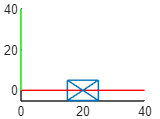

'orbit'은(는) 인식할 수 없는 함수 또는 변수입니다.


for deg=0:4:720  % (2) :(1)의 최종 위치에서 x3축 기준으로 반지름이 20인 CCW로 2바퀴 등속도.. 하강 거리 -20(자전+공전)
    clf;
    % x1 x2 x3는 공전이 되는 궤도의 좌표
    x1=20*cos(deg*pi/180); % 공전을 반지름이 20인 원의 궤도를 따라서 한다. -> 원을 그리기 위한 x1좌표
    x2=20*sin(deg*pi/180); % % 공전을 반지름이 20인 원의 궤도를 따라서 한다. -> 원을 그리기 위한 x2좌표
    x3=-deg/(noRev*360)*20; % x3축 공전하는 것에 비례하면서 -20만큼 heave
    psi=deg*4*pi/180; % 공전 1바퀴에 자전 4번

    Rz_round=[cos(psi) -sin(psi) 0 x1;
        sin(psi) cos(psi) 0 x2;
        0 0 1 x3;
        0 0 0 1];
    y=Rz_round*d; % 팔면체 도형을 x1만큼 surge함, x2만큼 sway, x3만큼 heave, psi만큼 yaw-> y에 저장

    line([y(1,:) y(1,1)],[y(2,:) y(2,1)],[y(3,:) y(3,1)]);
    line([40 0 0],[0 0 0],[0 0 0],'Color','r');
    line([0 0 0],[0 40 0],[0 0 0],'Color','g');
    line([0 0 0],[0 0 0],[0 0 40],'Color','k');

    orbit1=circshift(orbit1,-1);
    orbit2=circshift(orbit2,-1);
    orbit1(end,:)=[y(1,1) y(2,1) y(3,1)];
    orbit2(end,:)=[y(1,2) y(2,2) y(3,2)];
    % 누적된 좌표가 과거일수록 선이 연하게 그려지는 것을 구현하기 위해
    % circshift 함수(기능 : 배열을 순환적으로 이동)를 이용하여 과거 궤도의 좌표를 계속 기억하는 oribt행렬을 만들 것이다
    % circshift(orbit,-1)은 n행을 n-1행으로 위치를 이동, 1행은 마지막행으로 이동을 의미한다.
    % 따라서 orbit행렬의 39번째 행이 가장 최근 궤도의 좌표이며 
    % 1번째 행이 orbit행렬에 저장된 좌표들 중 가장 과거 궤도의 좌표이다.
    % 팔면체 꼭지점 변수 orbit1과 팔면체(5,-5,0)꼭지점 변수 orbit2 둘 다 위의 기능이 수행된다.

    % 궤도좌표가 누적된 행렬변수인 orbit의 x1,x2,x3를 1행부터 39행까지(가장 과거 궤도~가장 최신 궤도) 출력할 것이고,
    % 선의 색깔은 n행이면 n만큼의 진한 정도를 갖는다. 
    % 따라서 과거의 누적된 좌표일수록 선이 연하게 그려질 것이다.
    % 팔면체 꼭지점 변수 orbit1과 팔면체(5,-5,0)꼭지점 변수 orbit2 둘 다 위의 기능이 수행된다.
    for j=1:size(orbit1,1)-1
        line([orbit1(j,1) orbit1(j+1,1)],[orbit1(j,2) orbit1(j+1,2)],[orbit1(j,3) orbit1(j+1,3)], ...
            'Color',linc1(j,:),'LineWidth',2);
        line([orbit2(j,1) orbit2(j+1,1)],[orbit2(j,2) orbit2(j+1,2)],[orbit2(j,3) orbit2(j+1,3)], ...
            'Color',linc2(j,:),'LineWidth',2);
    end

    for i=1:1:8
        patch([y(1,p(i,1)) y(1,p(i,2)), y(1,p(i,3))], ...
            [y(2,p(i,1)) y(2,p(i,2)), y(2,p(i,3))], ...
            [y(3,p(i,1)) y(3,p(i,2)), y(3,p(i,3))],c(i));
    end
    xlabel('x1-axis');ylabel('x2-axis');zlabel('x3-axis');
    axis([-60 60 -60 60 -60 60]);
    az2=az+deg/2; 
    % 문제요구에 맞게 나선운동하는 동안 azimuth는 90부터 450도까지 변화 (직선운동 for문이 끝나면 az==90 deg==0, 나선운동 끝날때 az2==90+720/2==450)
    el2=el-75*sind(deg);
    % 문제요구에 맞게 나선운동하는 동안 Elevation는 45부터 -45도까지 변화 (직선운동 for문이 끝나면 el==45 deg==0, 나선운동 끝날때 el2==45-75*(1)==-30)
    % sind는 deg(도)의 sin값을 나타낸다. 따라서 sin(720)==1
    view(az2,el2); grid;
    pause(0.000001);
end